## Kommunikation eksamens eksempler

**Network:**

**Problem 1.**

- **Fcking wireshark opgave :)**

**Problem 2.**

**Assume that it takes 1 ms from a bit leaves A to the bit is received in B. Assume also that the**

**bandwidth of the line is 5Mbit/s. How long does it take to transfer the frame of 1500 bytes from A to B?**

**(round to nearest ms).**

- Total time  equation: $1\textrm{ms}+\left(\frac{1500\textrm{byte}\cdot 8}{5\textrm{Mbit}/s}\right)=3\ldotp 4\textrm{ms}$

t = 1e-3;
bw = 5E6;
frame = 1500*8;
trans_time = frame/bw;
prop_time = 0.001;
total_time = trans_time + prop_time;

**Problem 3.**

**What is the difference between error detection and error correction. Give an example where it is more**

**suitable to use error correction mechanisms.**

- Error correction: Enough redudant information along with each block of data sent to enable the receiver to deudce what the transmitted data must have been.

- Error detection: Only include enough redudancy so the receiver can deduce that an error occured but which error and have a request of retransmission.

- Example: In wireless links that make many errros, it is better to add enough redundancy to each block for the receiver to be able to figure out what the original block was rather then relying on a retransmission, which itself may be in error.

**Problem 4.**

**Which layer header contains **

**a) MAC address**

- Data link layer - Layer 2

**b) Destination IP address**

- Network layer - Layer 3

**c) SYN bits when a connection is established (hvor kommer du fra)**

-   Transport layer - Layer 4 typically TCP header.

**Problem 5.**

**What is the purpose of Inter Frame Space in 802.11 MAC protocol?**

- Wireless devices in a network share the same channel. The IFS introduces a mandatory delay between consecutive frame transmissions to reduce the likelihood of collisions.

- Different types of frames require different levels of priority. For example, control frames like **ACKs** (acknowledgiments) or **RTS/CTS** (Request to Send/Clear to Send) have higher priority than regular data frames. The IFS provides a mechanism to enforce this prioritization

- Side 308 i Tanenbaum Computer networks.

**Problem 6.**

**a) Why authentication is needed? **

- To ensure that the communication partner is who it is supposed to be and not an imposter.

**b) Given that two devices share a common secret, how authentication can be done?**

- Through a challenge-response. Bob and Alice share a secret key. 

- Alice sends her identity A, to Bob in a that Bob understands. Bob doesnt know if this came from Alice so he needs a large random number back Rb to alice as a challenge. Alice gets this message encrypts it with KAB and sends it back. Now Bob knows its Alice but Alice does not so she sends a large random number to Bob. Bob then encrypts that with same secret key back to Alice and connection is established.

**Workshop Assignment:**

**Problem 1**

(a) Determine the total number of overhead bits contained in the transmission of a single TCP segment using the protocol stack.

- Transport layer: 20 bytes header, 536 payload.

- Internet layer(IPv4): 20 bytes + TCP segment total 556 bytes.

- link/ppp: 4 bytes (2 flag som ikke tælles med i hamming men efterfølgende for differens)

Husk at læse opgavebeskrivelsen helt igennem så giver det bedre mening  der stå at encoding tager ppp header og undlader at tage flagene.


$$\textrm{total}\;\textrm{overhead}\;\textrm{bits}=\;\textrm{ceil}\left(\frac{\textrm{overhead}\;i\;\textrm{bits}+\textrm{payload}\;i\;\textrm{bits}}{502\left(\textrm{data}\;\textrm{bits}\;\textrm{hamming}\right)}\right)\cdot 511\left(\textrm{total}\;\textrm{hamming}\;\textrm{bits}\right)$$


bits_after_encoding = ceil((((4+20+20+536)*8)/502)) * 511

bits_after_encoding =         5110


Efter fundet totalt antal bits efter enconding så trækkes payloadens størrelse fra for at finde ud af hvor mange redudancy bits der er tilstede

overhead = bits_after_encoding + (2*8) - (536*8)

overhead =    838


(b) Consider that Zoya and Yoshi are connected by a communication link that can reach a maximum rate of 10 Gbit/s.

Determine the maximum throughput achieved by the system. 

- Maximum throughput: $\textrm{Maximum}\;\textrm{datarate}=\textrm{BW}\cdot \frac{P\left(\textrm{payload}\;\textrm{size}/\textrm{goodput}\right)}{S\left(\textrm{packet}\;\textrm{size}/\textrm{throughput}\right)}$ 

bw = 10e9;
max_throughput = 10E9 * (536*8)/((536*8)+overhead);
num2sip(max_throughput) %gigabit

ans = '8.3652 G'

(c) Consider that the bits of the TCP segment are transmitted over a twisted pair cable using baseband BPSK modulation with polar rectangular pulses. Zoya needs to stream 60 Hz 1080p video, which requires a bitrate of 12 Mbit/s. Determine the minimum bandwidth required by the communication system in this case.

- Samme procedure som i b) her anvender man bare at 12Mbit/s er kendt og deraf skal finde din data rate for at opretholde en bitrate på 12Mbit/s?

syms BW
bitrate = 12E6;
max_rate = solve(BW*(536*8)/((536*8)+overhead)==bitrate,BW);
BW_bspk = max_rate*2;
var = vpa(BW_bspk)

$$var = 28690298.507462686567164179104478$$

num2sip(28690298.507462686567164179104478) %Mhz

ans = '28.69 M'

**"Since, in this case, the BPSK transmission uses a rectangular polar pulse shape, the bandwidth of the baseband signal is twice the data rate. Therefore, the minimum bandwidth required by the system is: B = 2R = 28.5 MHz-wiki måske-lec 11 slide 34"**

(d) Determine the total bandwidth required by the communication system with the same setup of item (c) but assuming wireless communication by using conventional amplitude modulation.

- Since AM has double sideband signals the AM signals bandwidth is twice the size of the baseband bandwidth which from ex. c)

am_bandwidth = 2*BW_bspk;
vpa(am_bandwidth); %Mhz

(e) Now, considering the same setup of item (d), assume that the communication stream of Zoya and Yoshi shares a 200 MHz channel with four other ones with the same characteristics. The five streams divide the channel equally using TDMA. Determine the maximum data rate that can be achieved by Zoya and Yoshi’s stream. Check whether the rate allows the transmission of 60 Hz 1080p video in real-time.

- Du divider med 2 to gange netop på grund af modulationen fra BPSK og AM fra tidligere og det resultere så i en rest på 50 MHz de 5 par kan bruge som så skal fordeles ud til dem hver.

channel_bw = 200E6/4 % 4 tallet forekommer grundet at du demodulere to gange fra AM til BSPK til ren signal?? %Mhz

channel_bw =     50000000


Herefter del den 5 fordi de deler denne bandwidth grundet tdma:

50e6/5 %dunn %MHz

ans =     10000000


Since this is lower than the 14.3Mbits/s they cannot stream in that channel of 200Mhz. dayum sad ;(

**Problem 2**

a) Let us assume repetition code, in which each bit is repeated m times. As a first step, formulate the packet error rate, given the Bit Error Rate (BER) $p_e$.

- Formula for packet error rate lecture 11: $P_{\epsilon \;} =\sum_{k=\left\lceil m/2\right\rceil }^m \left\lbrack \begin{array}{c}
\;m\\
k
\end{array}\right\rbrack \cdot \;P_e^k \cdot {\left(1-P_e \right)}^{m-k} \;$Se packet_error_rate_problem_2 i folderen.

(b) Let us now assume BPSK modulation, considering an AWGN channel. Then, describe the BER by using the signal-to-noise ratio (SNR) per bit $\gamma {\;}_b$.

- For BPSK this is known: $P_b =Q\left(\frac{2\sqrt{\;E_b }}{\sqrt{2N_0 }}\right)=Q\left(\frac{\sqrt{2\;E_b }}{\sqrt{N_0 }}\right)=Q\left(\sqrt{\;2\gamma {\;}_b }\right)$where gamma is you know... This is inserted into the formula from before so

- 
$$P_{\epsilon \;}^B \left(m\right)=\sum_{k=\left\lceil m/2\right\rceil }^m \left\lbrack \begin{array}{c}
\;m\\
k
\end{array}\right\rbrack \cdot \;p_{\gamma }^k \cdot {\left(1-p_{\gamma } \right)}^{m-k}$$


(c) To realize packet error rate below ϵ, how many repetitions are needed at minimum? First, formulate the problem, then based on grid search or a similar method, obtain

the minimum value for $\gamma_b$ ∈ [0, 20]. With the data points, plot a figure where the horizontal axis is the reliability requirement ϵ, and the horizontal axis is an optimal value of m

Answer:

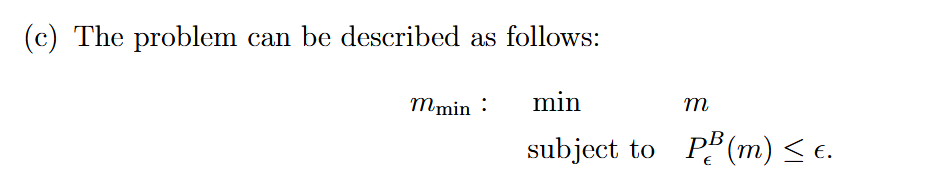find en m(bits) som altid giver $P_{\epsilon \;}^B$(packet error rate) mindre end $\epsilon \;\left(\textrm{reliability}\;\textrm{requirement}\right)$

Gridsearch:

 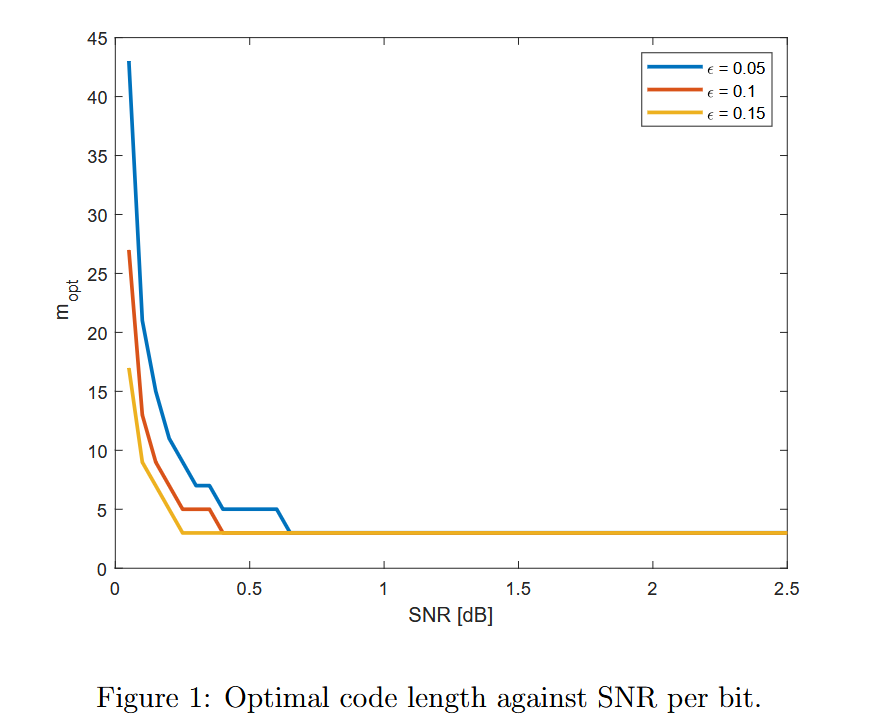

**Problem 3**

Here, we consider an IoT data collection scenario in which N IoT devices are deployed over the communication area of a Base Station (BS). This requires us to consider medium access control. In this problem, we compare the performance of TDMA and random access methods to maximize the system level performance. The time is divided by a frame, which is composed of L uplink slots. The length of slots corresponds to the length of the packet. For simplicity of analysis, we consider the collision channel, in which collision happens if multiple nodes transmit data in the same time slot. We assume that each node has a meaningful packet at the time of query with probability d ∈ [0, 1]. Here, meaningful data is defined as the data that is interesting to the receiver. In the TDMA scheme, the BS first transmits the control signal, including scheduling information. To simplify our analysis, this problem ignores the overhead of the control signal. As a scheduling method, in this problem, we assume well-known round-robing methods, in which each node transmits its packet in a predetermined order. Specifically, the node i ∈ [N ] transmits its packet at the i-th slots, where [N ] denotes a set with N elements. In real-time systems, it is important to collect by the deadline to respond to query requests from external users. In this case, the data that does not succeed in data transmission by the deadline has no value for the receiver. In this sense, designing a communication protocol to support the receiver’s goal is crucial. To this end, this problem investigates the successful probability of meaningful data, which is defined as the probability that the active user having meaningful data succeeds in data transmission within L slots. Having this in mind, answer the following items.

(a) Derive the transmission success probability for the round-robin scheme given L

- $P_s^{\textrm{TDMA}} =\min \left(1,\frac{L}{N}\right)$ hvis du har større antal slots L så er sandsyneligheden altid 1 for transmission men hvis antallet af slots L er mindre end antal devices N så bliver det forhold som definere Probalitity. 1, er tilstede for sandsynelighed ikke kan blive mere end 1.

(b) Derive the transmission success probability for framed ALOHA, given d and L. Note that the number of active users is a random variable, so you need to consider it to derive the success probability.

- To simplify the description, we define B(n, k, p) to represent the binomial distribution, n as the number of trials, k as the number of successes (the target outcome), p as the probability of success in a single trial.

- As we noted, its expectation can be derived by considering the distribution of the number of active users, which follows binomial distributions. The transmission success probability should be expressed as follows:

- Answer:$P_s^{\textrm{RA}} \left(L,N,d\right)=B\left(N,0,d\right)+\sum_{\omega =1}^N {\left(1-\frac{1}{L}\right)}^{\omega -1} B\left(N,\omega ,d\right)$ 

(c) Verify the validity of derived equations by comparing them with the simulation results.

- example from chat that plot simulation results from TDMA

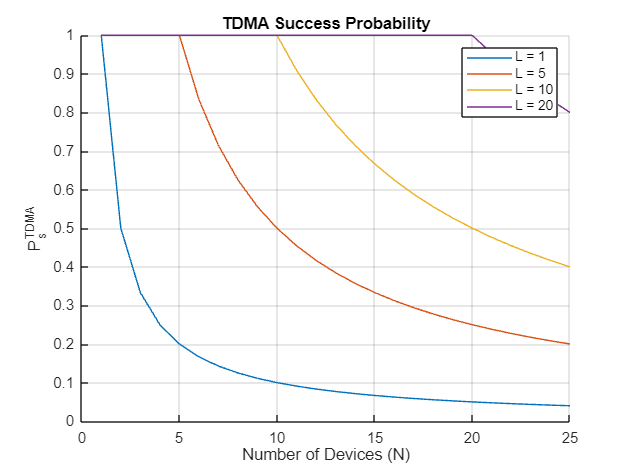

% Parameters
L_values = [1, 5, 10, 20]; % Different numbers of slots
N_values = 1:25;           % Range of device numbers

% Initialize matrix to store results
P_s_TDMA = zeros(length(L_values), length(N_values));

% Compute P_s for each combination of L and N
for i = 1:length(L_values)
    L = L_values(i);
    for j = 1:length(N_values)
        N = N_values(j);
        % Compute P_s using the given formula
        P_s_TDMA(i, j) = min(1, L / N);
    end
end

% Plot the results
figure;
hold on;
for i = 1:length(L_values)
    plot(N_values, P_s_TDMA(i, :), 'DisplayName', sprintf('L = %d', L_values(i)));
end
hold off;

% Customize plot
xlabel('Number of Devices (N)');
ylabel('P_s^{TDMA}');
title('TDMA Success Probability');
legend('show');
grid on;

It shows that largest proability is one when L is equal to or greater than N however as N increases the proability of a succesfull transmission decreases. 

- For framed aloha:

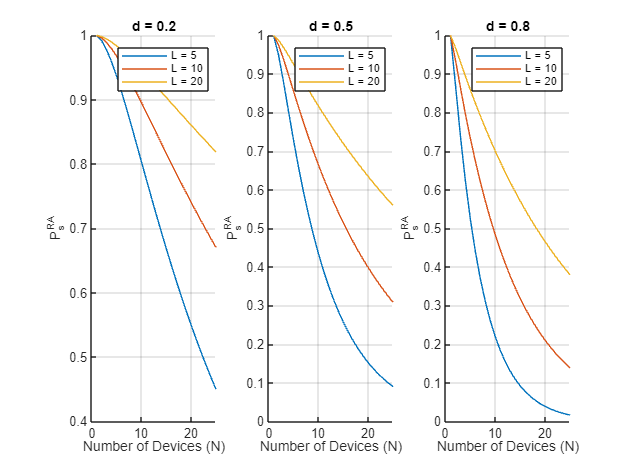

%%Chat cook
% Parameters
L_values = [5, 10, 20]; % Number of slots
N_values = 1:25;        % Number of devices
d_values = [0.2, 0.5, 0.8]; % Probability of meaningful data

% Initialize results matrix
P_s_RA = zeros(length(L_values), length(N_values), length(d_values));

% Binomial distribution function
binomial_B = @(N, omega, d) nchoosek(N, omega) * d^omega * (1-d)^(N-omega);

% Compute P_s for each combination of L, N, and d
for l = 1:length(L_values)
    L = L_values(l);
    for n = 1:length(N_values)
        N = N_values(n);
        for d = 1:length(d_values)
            prob_d = d_values(d);
            
            % Compute the first term (B(N, 0, d))
            P_s = binomial_B(N, 0, prob_d);
            
            % Add the summation term
            for omega = 1:N
                P_s = P_s + (1 - 1/L)^(omega - 1) * binomial_B(N, omega, prob_d);
            end
            
            % Store result
            P_s_RA(l, n, d) = P_s;
        end
    end
end

% Plot results
figure;
for d = 1:length(d_values)
    subplot(1, length(d_values), d);
    hold on;
    for l = 1:length(L_values)
        plot(N_values, squeeze(P_s_RA(l, :, d)), 'DisplayName', sprintf('L = %d', L_values(l)));
    end
    hold off;
    xlabel('Number of Devices (N)');
    ylabel('P_s^{RA}');
    title(sprintf('d = %.1f', d_values(d)));
    legend('show');
    grid on;
end

**Expected Results:**

- **When **d** is small (d****→****0****):**

- $P_s^{\textrm{RA}}$ will be close to 1 because most devices are unlikely to transmit.

- **When ** **d****→****1****:**

- $P_s^{\textrm{RA}}$decreases as N increases because more devices transmitting leads to higher contention.

- **Impact of **L**:**

- Larger L (more slots) increases $P_s^{\textrm{RA}}$, as the likelihood of slot conflicts decreases.

(d) Characterize the performance with respect to L for both TDMA and random access.  Plot the results of success probability against L for different values of d, where we set N = 100, d = 0.05, 0.01, and select L within the range of [10, 100] with the step of 10.

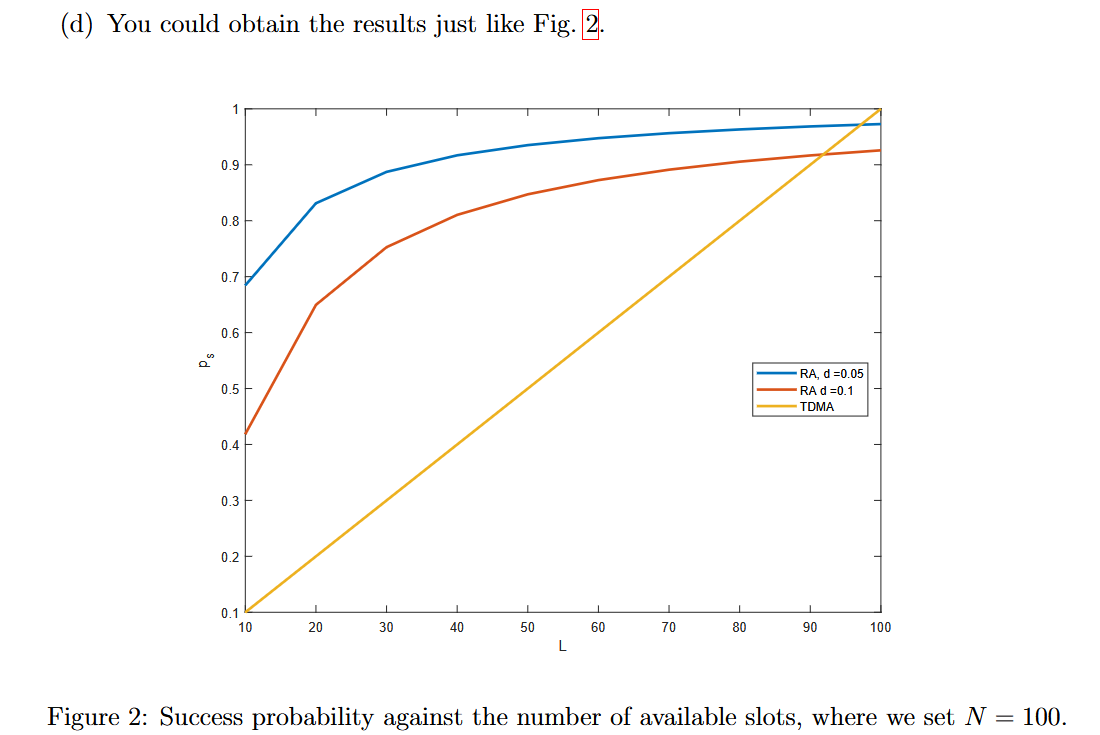

e)

Answer:

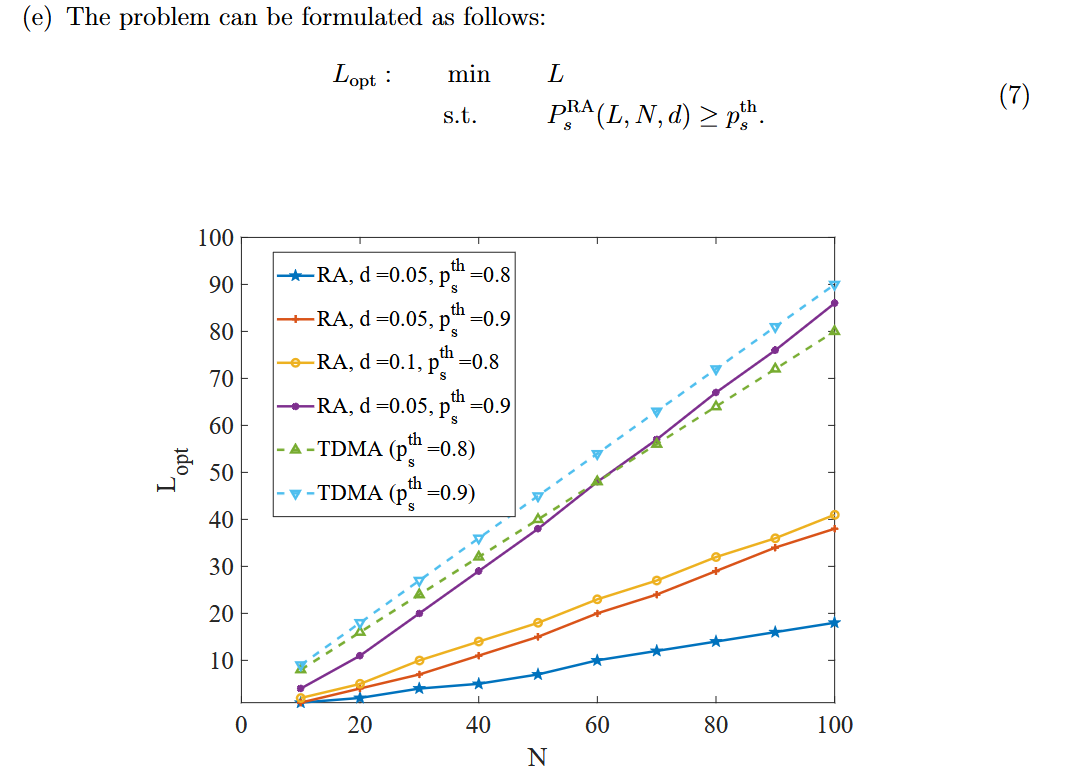

**Modulation part extra exercises:**

*Ex. 1 Se github for billede*

*Your friend has bought two Icom IC-9100, a multiple band HF/VHF/UHF radio capable of doing FM modulation and demodulation. He is using them to transmit a modulating signal *$m\left(t\right)=2\cos \left(2\pi 1000t\right)$*. The power of the FM signal is 50 W, and it has a carrier *$f_c =100\textrm{Mhz}$* frequency of MHz and a peak frequency deviation *$\Delta \;f=10$* kHz.*

a) Write the waveform expression for the FM waveform without any integral

- (lecture 12 slide 63) $\textrm{modulated}\;\textrm{wave}:A_c \cos \left\lbrack 2\pi \;\left(f_c t+k_f \int_0^t \;m\left(\tau \;\right)d\tau \right)\right\rbrack$calculate the integral?? $\int_0^t \;m\left(\tau \;\right)d\tau =\int_0^t \;2\cos \left(2\pi 1000\tau \;\right)d\tau =\frac{\sin \left(2000\,\pi \,t\right)}{1000\,\pi }$

syms t
int(2*cos(2*pi*1000*t),t,0,t)

$$ans = \frac{\sin\left(2000\,\pi \,t\right)}{1000\,\pi }$$


$$P_c =50W=\frac{A_c^2 }{2}\Leftrightarrow A_c =2\sqrt{50}=10$$



$$\Delta f=A_m k_f \Leftrightarrow k_f =\frac{10\textrm{E3}}{2}=5\textrm{kHz}/V$$


$f_m =1000\textrm{Hz}$ (dette er fra de 1000 i cos funktionen)


$$\beta =\Delta f/f_m =10$$


Plug in the values missing giving: $10\cdot \;\cos \left\lbrack 2\pi \left(100\textrm{E6}\cdot t+5\textrm{E3}\frac{\sin \left(2000\,\pi \,t\right)}{1000\,\pi }\right)\right\rbrack$

close all
clear
syms t x
test = int(2*cos(2*pi*1000*t),t,0,t);
tt = solve(50 == x^2/2,x);

b) *Determine the approximated bandwidth of the FM waveform. Is the modulated signal a Narrow-Band or a Wide-Band Signal? (explain)*

- Approximated bandwidth? Carsons rule $\textrm{BW}\approx 2\left(\Delta f+f_m \right)=2\left(10\textrm{E3}+1000\right)=22\textrm{kHz}$

- Since $\beta =10$we have a wideband FM signal? Electronic notes: under 0.5 narrowband og over wideband :) elelrs så se tannenbuam.

*Your friend is very curious about the possibilities of the Icom IC-9100, and he is now considering the option of digitalizing the information and using BFSK as modulation scheme, with a space frequency of *$f_{\textrm{space}} =99\ldotp 95\textrm{MHz}$* and a mark frequency of *$f_{\textrm{mark}} =100\ldotp 05\textrm{MHz}$

*c) If the digital signal is transmitted at a rate of *$R_b =3$*kbps, how much bandwidth is needed for the BFSK transmission?*

For Bbfsk er M = 2 grundet at frekvensen kan repræsentere to symboler. :)

- 
$$B_{\textrm{BFSK}} \approx f_{\textrm{mark}} -f_{\textrm{space}} +2R_{\textrm{sym}}$$


- 
$$R_{\textrm{sym}} =R_b /\log_2 M=3\textrm{E3}/\log_2 \left(2\right)=3\textrm{kbauds}$$


- Put in values $B_{\textrm{BFSK}} \approx 100\ldotp 05\textrm{E6}-99\ldotp 95\textrm{E6}+2\cdot 3\textrm{E3}=106\textrm{kHz}$

***Ex. 2***

*Consider the baseband signal *$m\left(t\right)=2\cos \left(2\pi 100t\right)-\cos \left(2\pi 500t\right)$*. The signal is AM-modulated by a carrier wave c(t).*

*a) Determine the resulting (traditional) AM-signal *$v_{\textrm{AM}} \left(t\right)$* and plot the amplitude spectrum *$V_{\textrm{AM}} \left(f\right)$* when *$f_c =1500\textrm{kHz}$ *the carrier amplitude is *$A_c =10$ and the *amplitude sensitivity is *$k_a =0\ldotp 2$.

- (Lecture 12 slide 44) $s\left(t\right)=A_c \left\lbrack 1+k_a m\left(t\right)\right\rbrack \cos \left(\omega_c t\right)$ then plug in yielding: $10\cdot \left\lbrack 1+0\ldotp 2\cdot \left(2\cos \left(2\pi \;100t\right)-\cos \left(2\pi 500t\right)\right)\right\rbrack \cos \left(2\pi 1\ldotp 5\textrm{E6}\cdot t\right)$

- Plot spectrum:

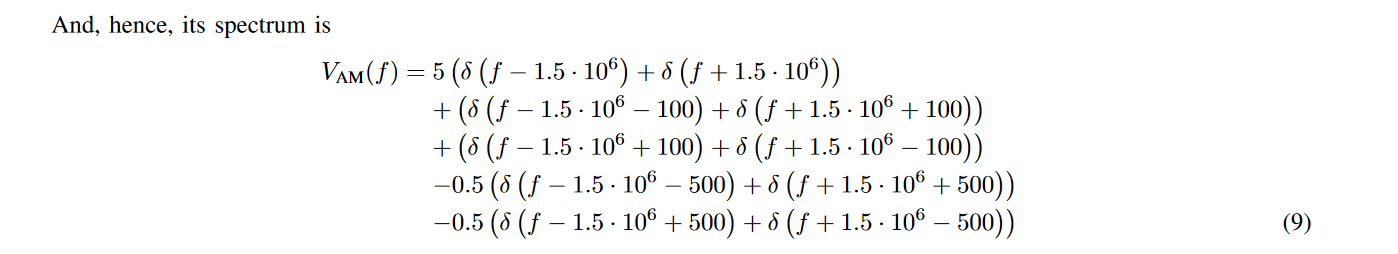

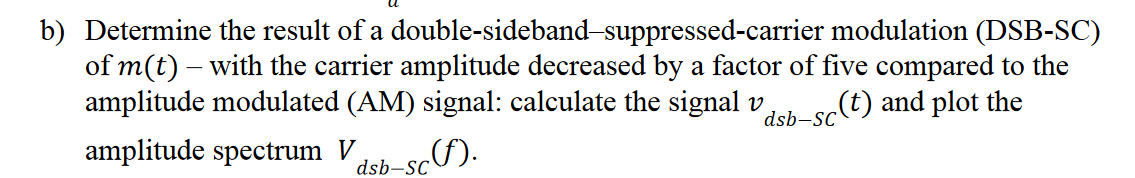

Answer:

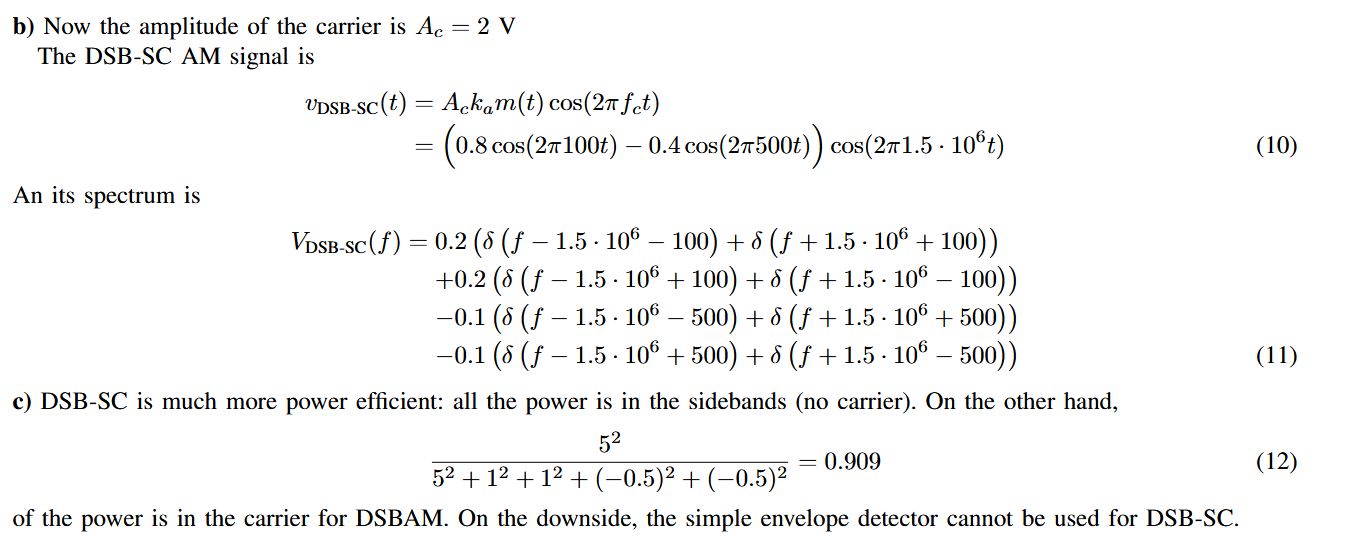

Answer:

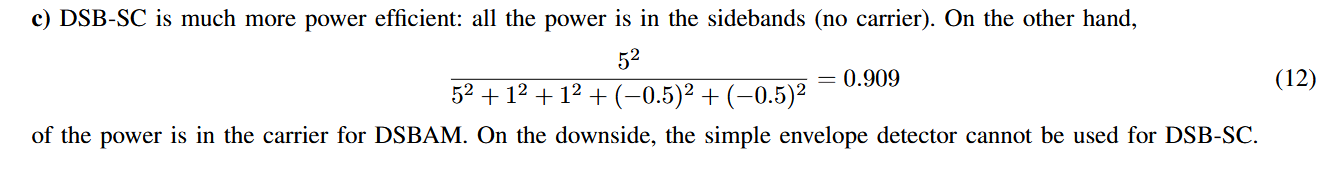

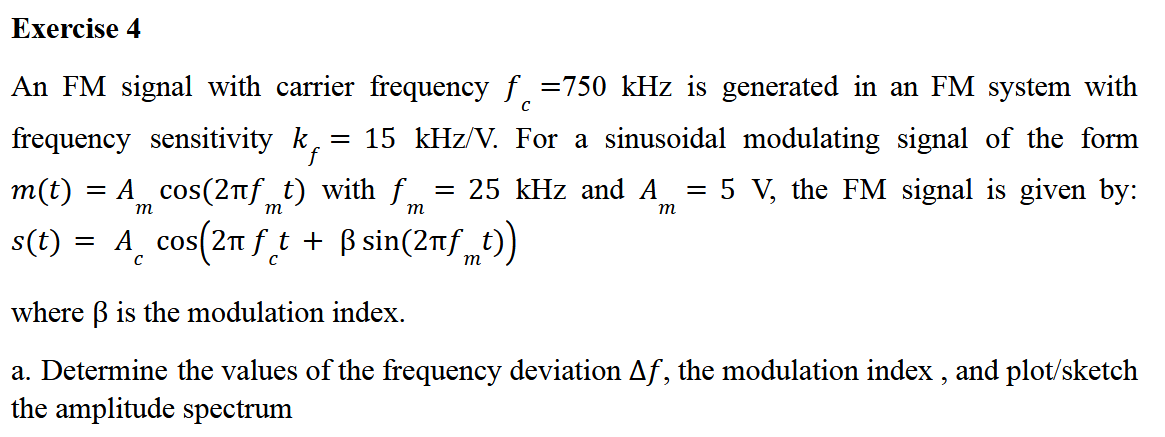

Answer: 


$$\Delta f=A_m k_f =5V\cdot 15\frac{\textrm{kHz}}{V}=75\textrm{kHz}$$



$$\beta =\frac{\Delta \;f}{f_m }=\frac{75\textrm{kHz}}{25\textrm{kHz}}=3$$


Amplitude spectrum:

Due to the Carson’s rule, 98% of the spectrum is contained within:


$$B_{\textrm{FM}} \approx 2\Delta f+2f_m^* =150\textrm{e3}+20\textrm{e3}=170\textrm{kHz}$$


delta_f = 5*15e3;
beta = delta_f/25e3;

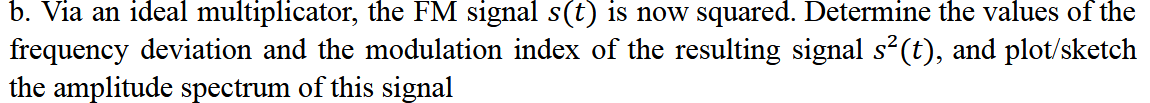

Answer:

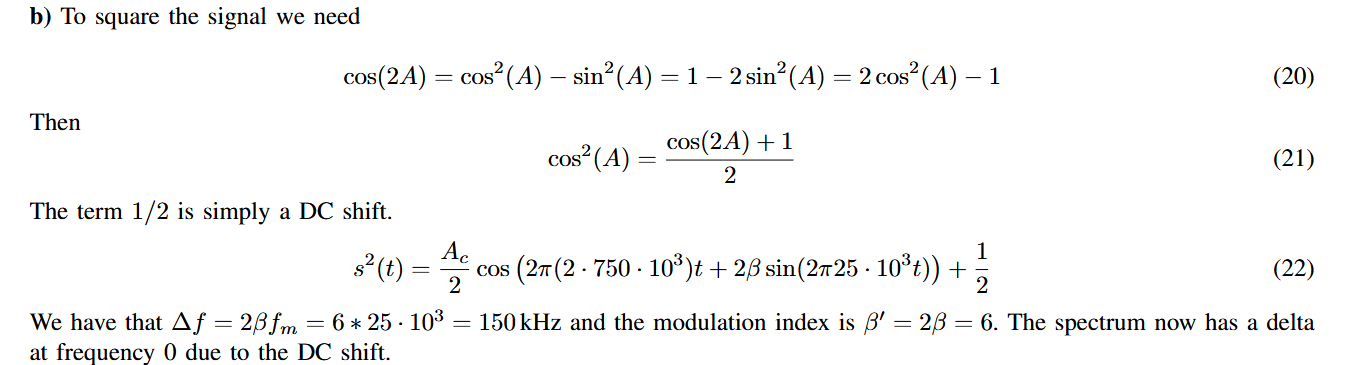

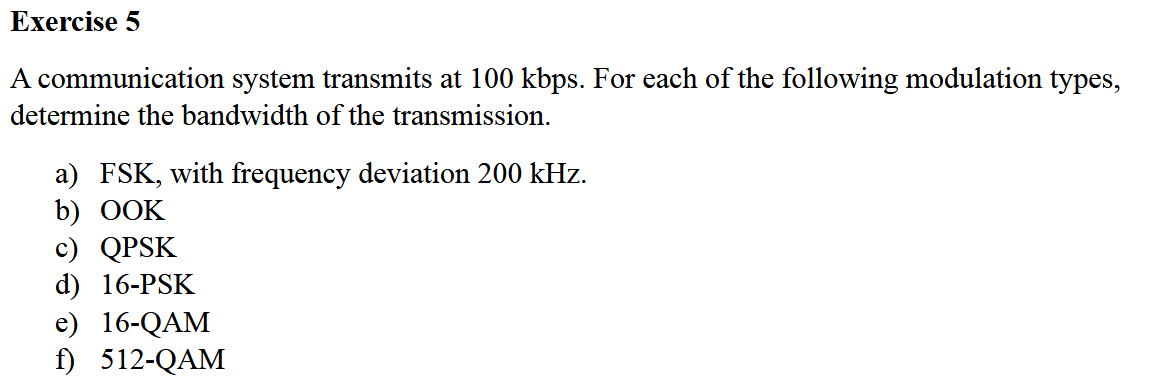

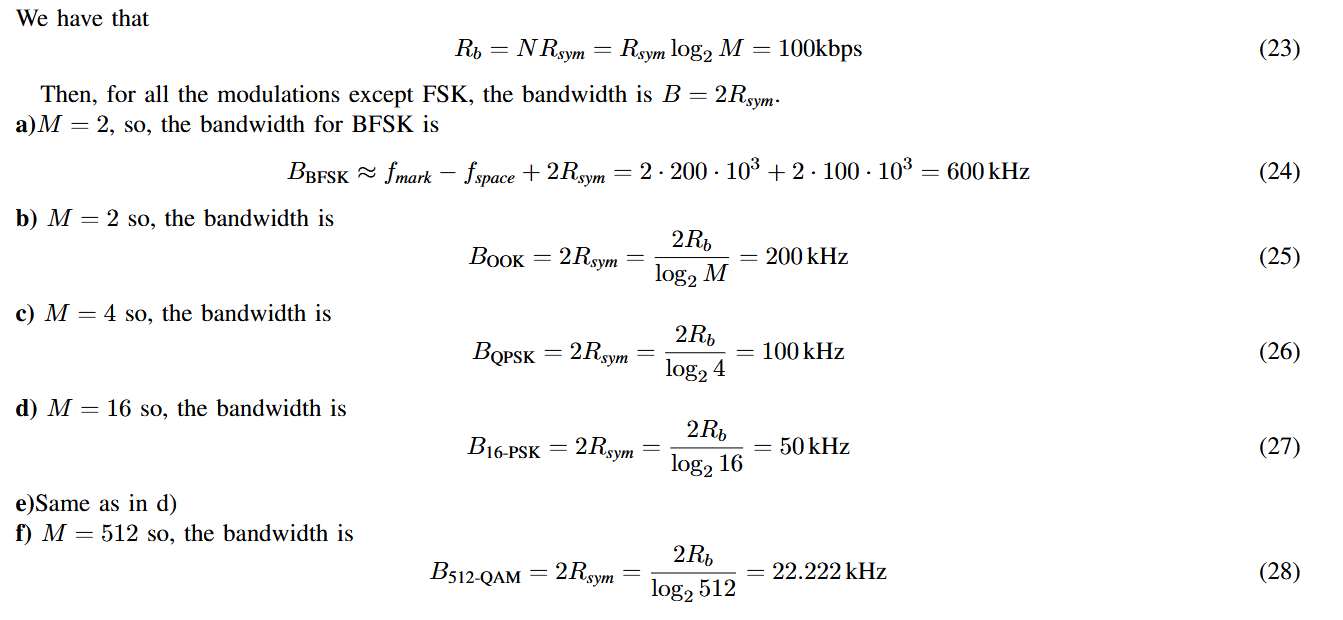

## Old modulation exam

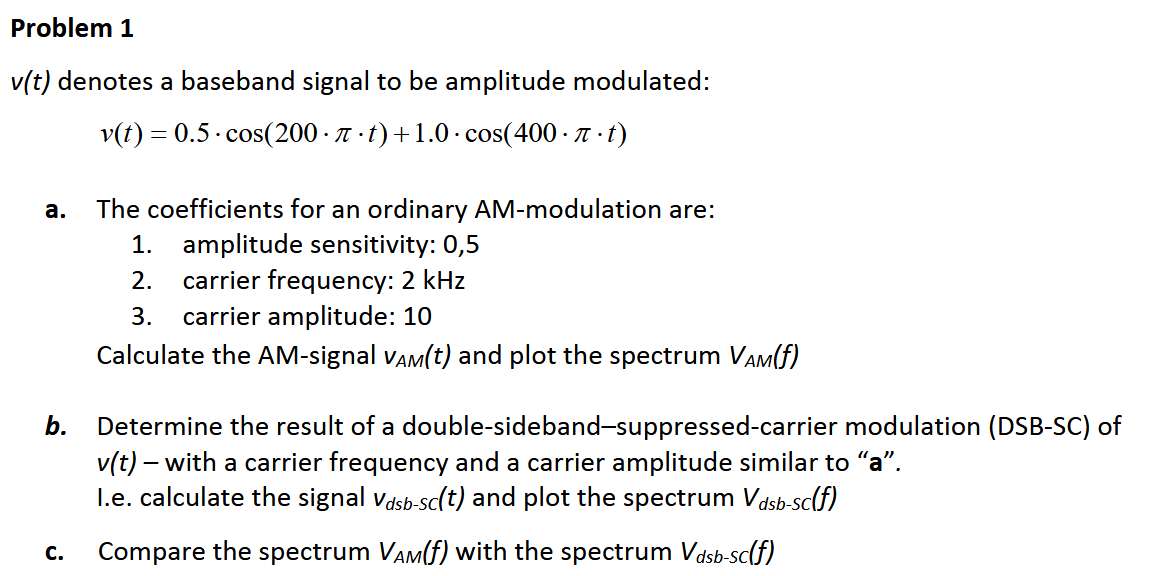

a) Answer:

Slide 45 i lec 12 og husk at kigge efter M(t) for spektrum. Ellers find løsning til lecture 12 det er den samme opgave!

ka = 0.5, fc = 2kHz, Ac = 10.

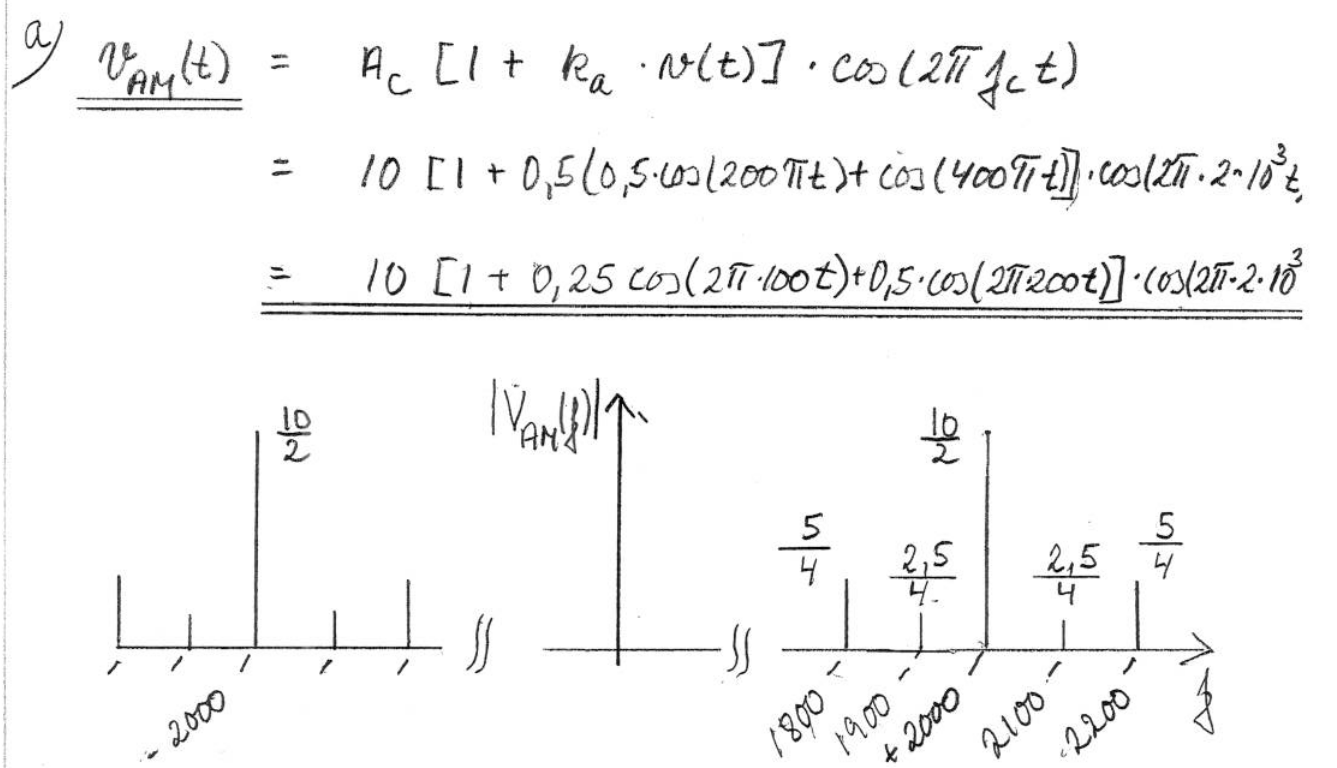

b) Slide 49 i lec 12 - man plotter bare ikke carrier fordi den ikke indgår i formlen :)) Hvilket er 2000 fra den tidligere opgave. 

c) Det ret trivielt at se der er forksel på de to.

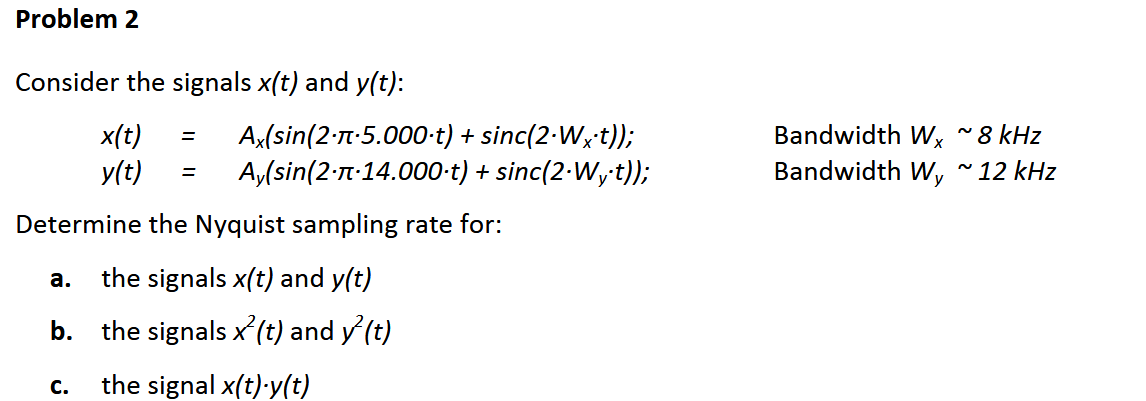

a) 16 og 24 khz

b) 32 og 56 khz. 

c) 44 khz Læg frekvenserne sammen for c for svarene fra a. og b. grundet det er i frekvens.

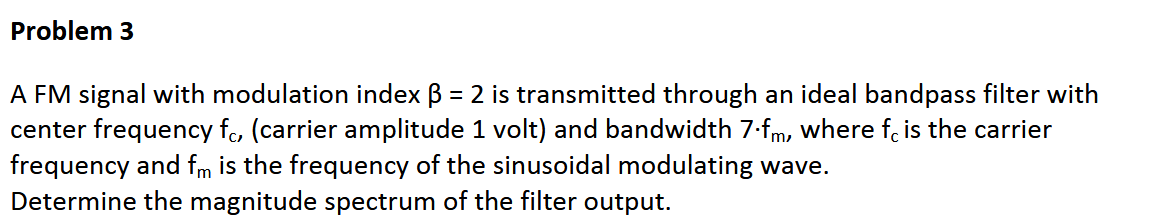

Answer:

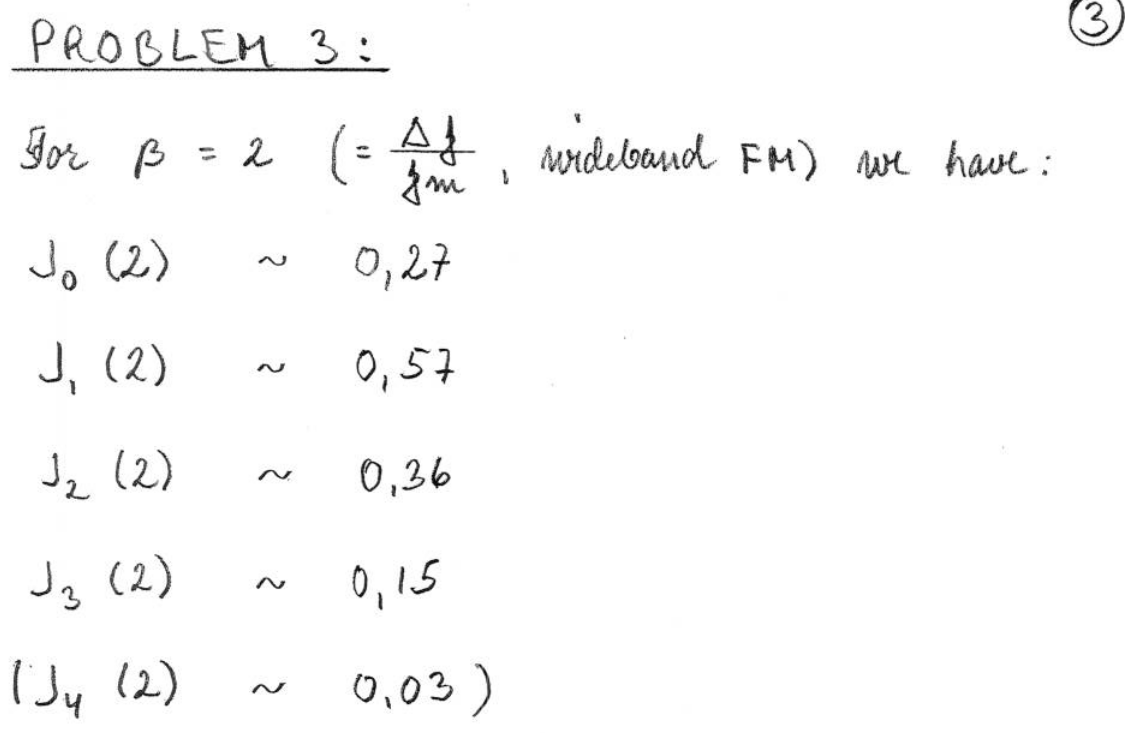

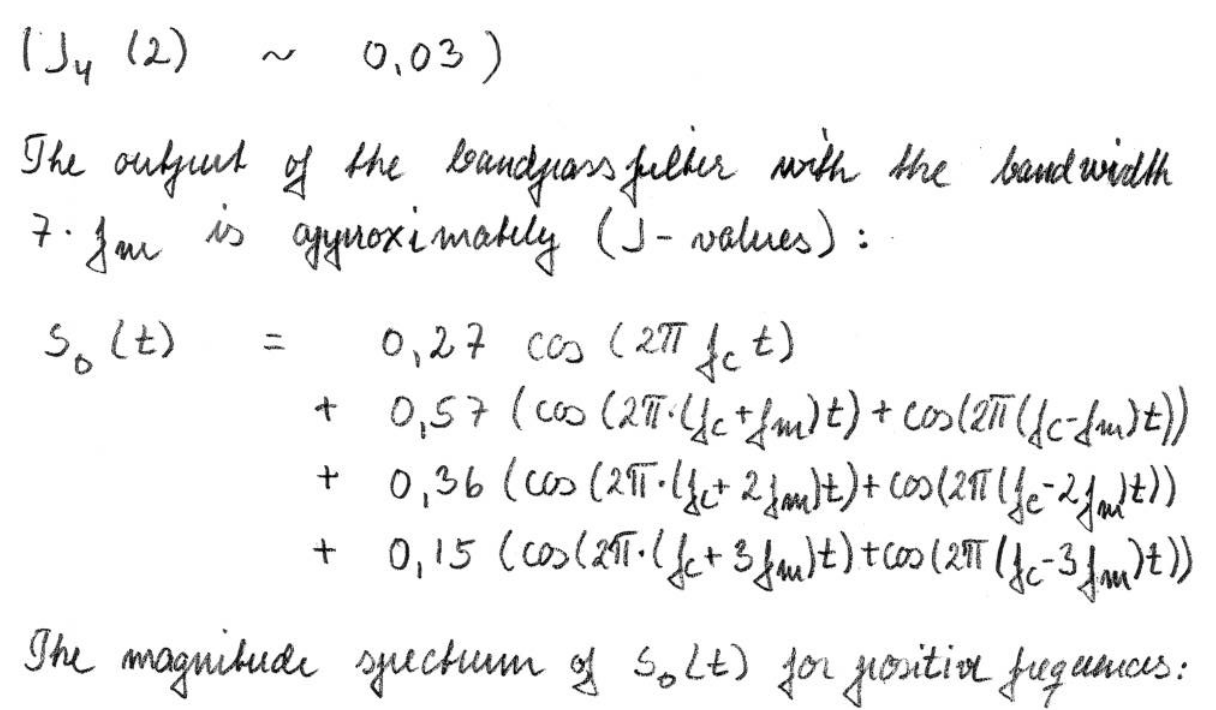

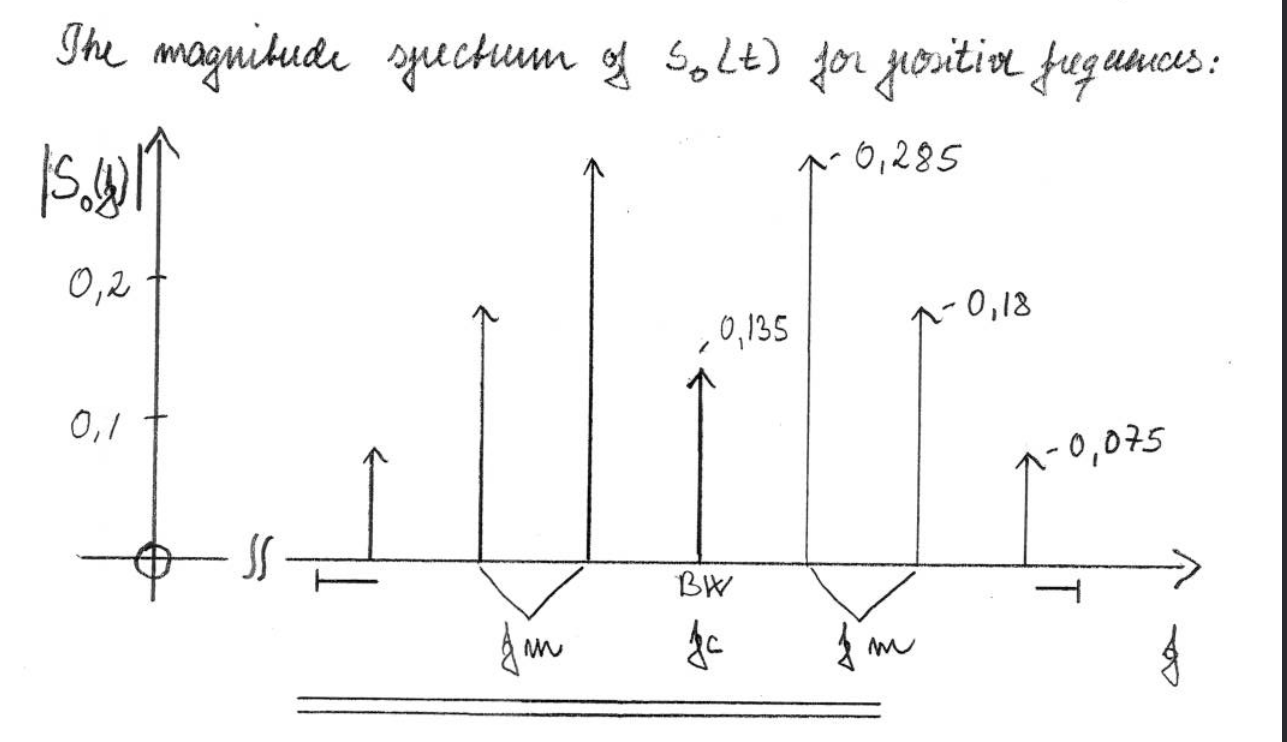

´Table of beta values for this exercise??

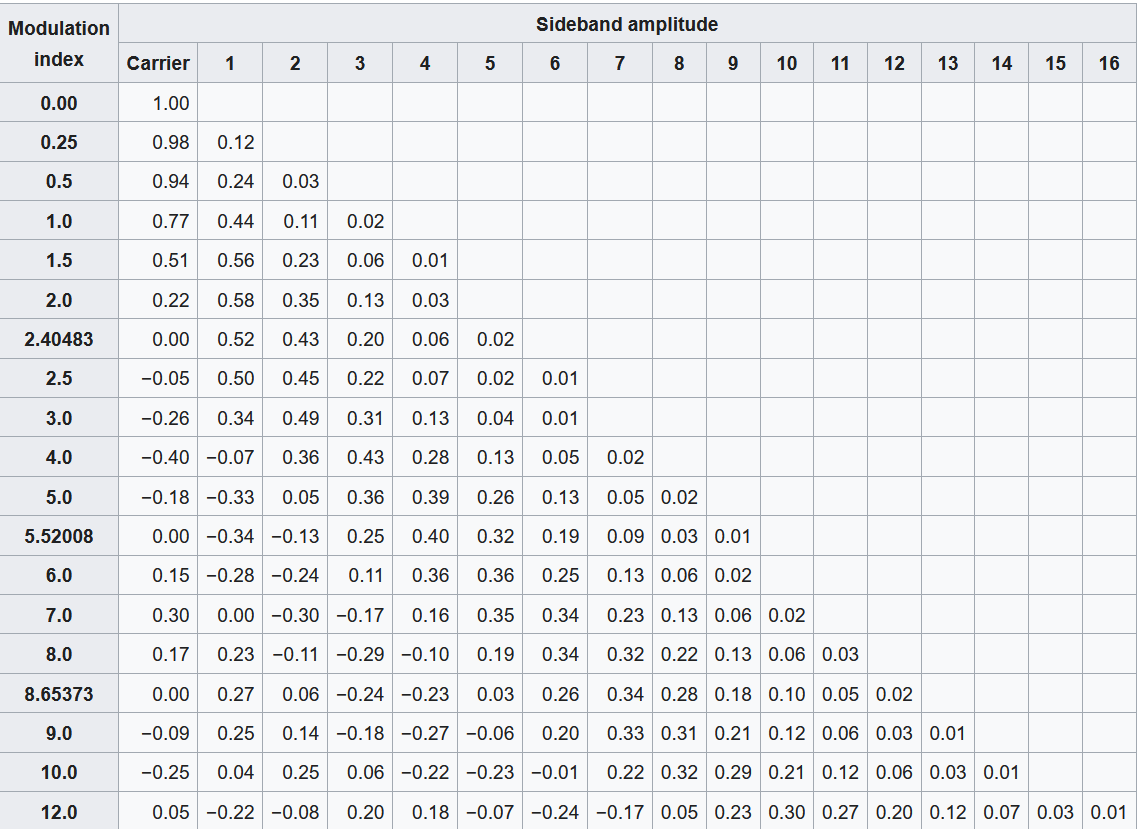

## Antenna part!

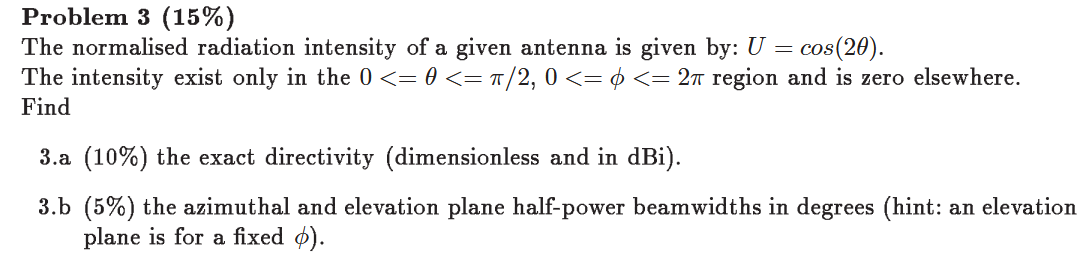

3.a

Answer:

Exact directivity? 


$$U=\cos \left(2\theta \;\right)\;$$


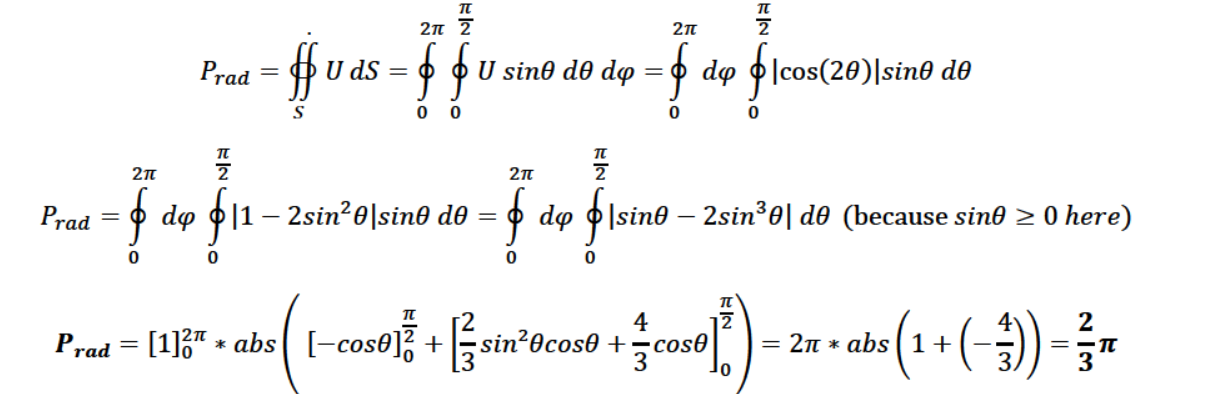

Så siger man at Umax er = 1.


$$D=\frac{\;4\pi U_{\max } }{P_{\textrm{rad}} }$$


close all
clear
syms t p
expr1 = abs(int((cos(2*t))*sin(t),t,0,pi/2)); %det skal være abs fordi effekt ikke kan være negativ.
ptot = int(expr1,p,0,2*pi)

$$ptot = \frac{2\,\pi }{3}$$

D = (4*pi*1)/(ptot);
DtoDb = pow2db(D);
vpa(DtoDb) % Nu i dBi :)

$$ans = 7.7815125038364363250876679797961$$

Answer:


$$U_{\max } \cdot \frac{1}{2}=\cos \left(\theta_h \right)$$


solve(cos(2*t) == 1/2)

$$ans = \left(\begin{array}{c} -\frac{\pi }{6}\\ \frac{\pi }{6} \end{array}\right)$$


$$\frac{\pi }{6}=0\ldotp 5236$$


Dette er kun en vinkel for HPBW og derfor skal man gange med 2 for at få det fulde spænd.

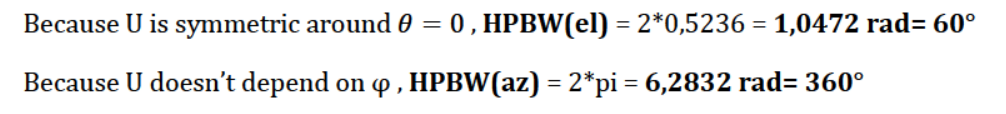

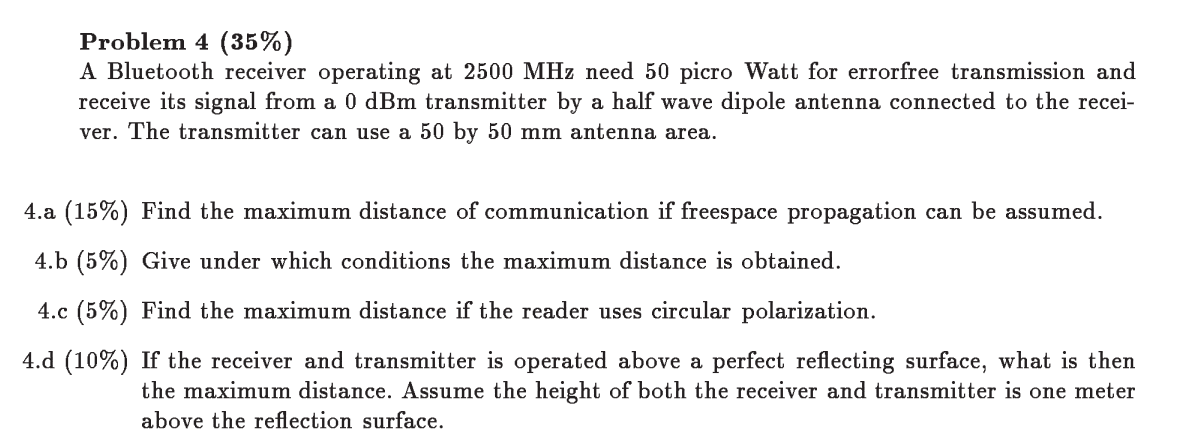

4.a

Answer:

0dbm = 1mw hvordan? Se gerts formel samling der er det i!

Dr for en halfwave dipole er 1.64 eller 1.63 dette er bare givet.

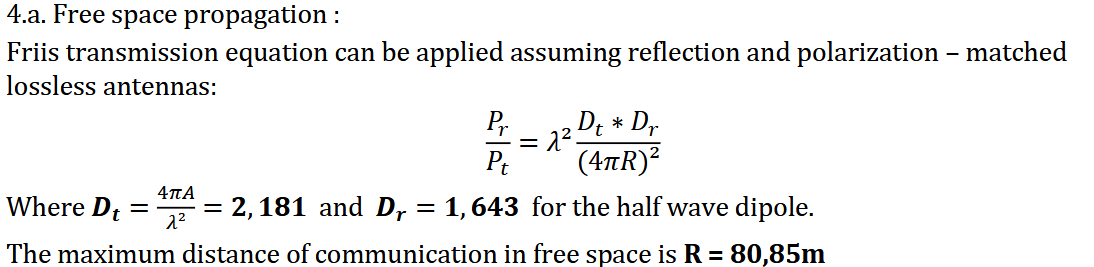

close all
clear
syms R
P_w = (1*10^(0/10))/(1000);
num2sip(P_w);
f = 2.5e9;
Pr = 50e-12;
A = 50e-3^2;
lam = 3e8/f;
Dt = (4*pi*A)/lam^2; %Hvor kommer dette fra find side tal?.
Dr = 1.643; %hvor fra? :D %Dette er givet for en half wave dipole.
maxd = solve(Pr == P_w*lam^2*((Dt*Dr)/(4*pi*R)^2),R);
vpa(maxd) %vælg positiv.

$$ans = \left(\begin{array}{c} -80.85350510336333206600273627161\\ 80.85350510336333206600273627161 \end{array}\right)$$

Answer:

- Line of sight no obstrucitons? Also high antenna gains?

- Perfect impedance matching

- Perfect polarization matching

- Lossless Antennas

Answer:

Bare halver det? Husk at tilføj det til ligningen for $\frac{1}{2}$eftersom det er circular polarizaed. 

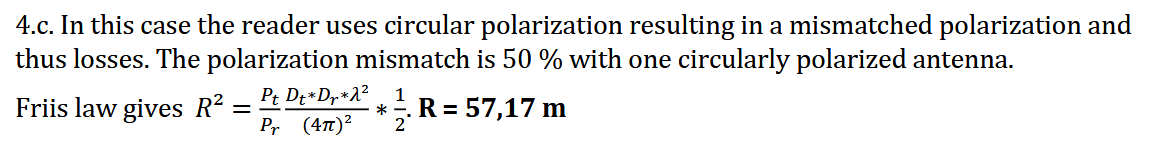

maxdhalf = solve(Pr == (1/2)*1e-3*lam^2*((Dt*Dr)/(4*pi*R)^2),R);
vpa(maxdhalf); 

Answer:

For lossless antennas: $\frac{P_r }{P_t }=D_t \cdot D_r {\left(\frac{h_t h_r }{R^2 }\right)}^2$ og valid for $R\ge \frac{4h_t h_r }{\lambda }=33\ldotp 33m\;\left(h_t =h_r =1m\right)$ hvor kommer du fra?.

ht = 1;
hr = 1;
maxdforreflective = solve(Pr == 1e-3*Dt*Dr*((ht*hr)/(R)^2)^2,R);
vpa(maxdforreflective) %igen vælg det positiv tal og ikke det med imaginær værdier.

$$ans = \left(\begin{array}{c} -92.016081502041643406529686409257\\ 92.016081502041643406529686409257\\ -92.016081502041643406529686409257\,\mathrm{i}\\ 92.016081502041643406529686409257\,\mathrm{i} \end{array}\right)$$

R = 92 meter. 